# **MATLAB ASSIGNMENT - 1**

## Read an image into a workspace variable

To import an image into the workspace variable,the "imread" function is used, where the filename is passed as an argument.

%Read an Image from inbuilt matlab images
img=imread("peppers.png");

## **Display the loaded Image**

To display the loaded image "imshow" function is used, additionaly the title of the image can be added using "title" function

imshow(img)

title('Peppers Image')

## Apply Image Processing Filter/effect to image


% Extracting each color plane to understand the colors of the image better
red_color_plane = img(:,:,1);
green_color_plane = img(:,:,2);
blue_color_plane = img(:,:,3);

% Enhancing the saturation of the red color plane by 1.4 times
enhanced_red = red_color_plane*1.4;

% Create an enhanced image with the boosted red color
enhancedImage = cat(3, enhanced_red, green_color_plane, blue_color_plane);

% Further the image contrast can be increased
filtered_img=histeq(enhancedImage);

%Here the image is further converted to gray with increase contrasr to highlight the required
% red color
grayscale_img=rgb2gray(filtered_img);
final_filter_img=imadjust(grayscale_img);

## Display the filtered image

%The filtered image is displayed using imshow and title to add title to the
%image
figure;
imshow(final_filter_img);

title('Filtered Image (Gray scale)');

## Save the resulting image to a .png file.

imwrite(final_filter_img, 'filtered_img.png');
disp('Filtered image saved as filtered_img.png');

Filtered image saved as filtered_img.png


## **Bonus**

%Select the input image
input_image="football.jpg";

%Select the filters to be applied
increase_contrast=false;
convert_gray_scale=true;

%Select the file format to save the image
img_format=".png";
final=[];

%Applying the required filters
if input_image ~= "Select"
    load_img = imread(input_image);
    if increase_contrast && convert_gray_scale
       constrast_img = histeq(load_img);
       final = rgb2gray(constrast_img); 
    elseif increase_contrast 
       final = histeq(load_img);    
    elseif convert_gray_scale
       final = rgb2gray(load_img);      
    else
        disp('Please select the filter');
    end
else
    disp('Please select the image');
end

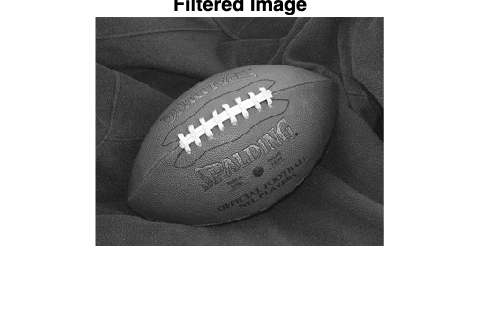

%Display the final edited image
figure;
imshow(final);    

title('Filtered Image');

%The filtered image is downloaded with the required extension
filename = 'bonus_filtered_img'+ img_format;
imwrite(final, filename);
disp(['Filtered image saved as ', filename]);

    "Filtered image saved as "    "bonus_filtered_img.png"

